syms f(g)
f(g) = 0;
x = 0:500:6000

x =            0         500        1000        1500        2000        2500        3000        3500        4000        4500        5000        5500        6000


y = [0 50 55 60 65 72 78 83 85 85 82 77 72]

y =      0    50    55    60    65    72    78    83    85    85    82    77    72


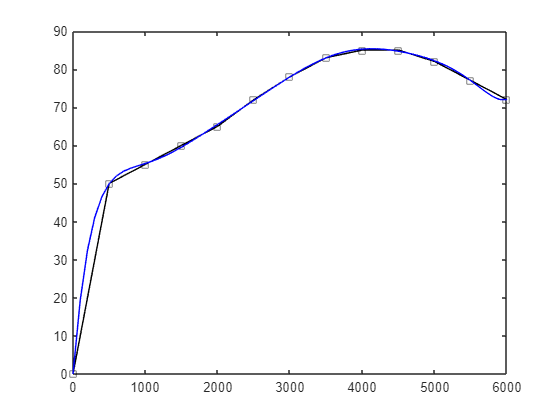

plot(x,y,'k-s')
hold on
z = [ 9.27185689e-30 -2.69196802e-25  3.33277639e-21 -2.29855128e-17 9.68752486e-14 -2.57578506e-10  4.28980804e-07 -4.25098468e-04 2.31965986e-01  7.85901406e-03];
for i=1:(length(z))
    f(g) = f(g) + z(i)*(g^(length(z)-i));
end
x_ = 0:100:6000;
y_ = f(x_);
plot(x_,y_,'b-')